clear

## Define a common colormap

newCmap = [255 255 255; 227 26 28; 31 120 180; 178 223 138; 51 160 44; 251 154 153; 166 206 227; 253 191 111; 255 127 0; 202 178 214; 106 61 154; 255 255 153; 177 89 40; 0 0 0;];
newCmap = newCmap ./ 255;

current_path = 'Z:\Jui-Yen Huang\Derived Files\Data\In vivo Calcium Imaging\20210914_0924_jRGECO1a_C57-C2-1\20210914_jRGECO1a_C57-C2-1_P11\P11_C2-1_AL_L3_140';

%current_path = 'Z:\Jui-Yen Huang\Derived Files\Data\In vivo Calcium Imaging\20210914_0924_jRGECO1a_C57-C2-1\20210918_jRGECO1a_C57-C2-1_P15\P15_C2-1_AL_L2_150';

%current_path = 'Z:\Jui-Yen Huang\Derived Files\Data\In vivo Calcium Imaging\20210914_0924_jRGECO1a_C57-C2-1\20210924_jRGECO1a_C57-C2-1_P21\P21_C2-1_AL_L3_180_stim'

suite2p_file_path =current_path + "/suite2p/plane0/Fall.mat"

suite2p_file_path = "Z:\Jui-Yen Huang\Derived Files\Data\In vivo Calcium Imaging\20210914_0924_jRGECO1a_C57-C2-1\20210914_jRGECO1a_C57-C2-1_P11\P11_C2-1_AL_L3_140/suite2p/plane0/Fall.mat"

culster_output_path = current_path + "/Modol_outputs/all.mat";
load (suite2p_file_path,"iscell","stat");
load (culster_output_path,"C0");
%% Make the ROI (x,y) locations
ROI_idx = find(iscell(:,1) == 1);
ROI_ID = ROI_idx-1;
stats_for_ROIs = stat(ROI_idx)';

yx = NaN(length(stats_for_ROIs),2);

 for z = 1:length(yx)
    yx(z,1:2) = stats_for_ROIs{z,1}.med;
 end

xy = zeros(size(yx, 1), size(yx, 2));
xy(:,1) = yx(:,2);
xy(:,2) = yx(:,1);
xy = round(xy);

clusterLocs_list = cell(1,length(C0));
centroidLocs = nan(length(C0),2);
convhull_list = cell(1,length(C0));

for idx = 1:length(C0)
    clusterLocs = xy(C0{idx}, :);
    clusterLocs_list{1,idx} = clusterLocs;
    centroid = [mean(clusterLocs(:,1)), mean(clusterLocs(:,2))];
    centroidLocs(idx,:) = centroid;
    convhull_list{1,idx} = convhull(clusterLocs(:,1),clusterLocs(:,2));
 end

% get coordinate of neurons that are not in cluster
ROI_ID_in_cluster = cell2mat(C0);
ROI_ID_not_in_cluster = setdiff(1:length(xy),ROI_ID_in_cluster);
non_clusterLocs = xy(ROI_ID_not_in_cluster,:);

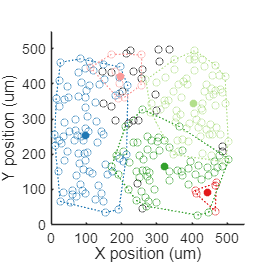

clf

% Plot the points
topography_figure = figure;

hold on

plot(non_clusterLocs(:,1), non_clusterLocs(:,2), 'o','Color','k');

for plot_idx = 1: length(C0)

    x = clusterLocs_list{1,plot_idx}(:,1);
    y = clusterLocs_list{1,plot_idx}(:,2);
    k = convhull_list{1,plot_idx};
    
    % Plot the points
    plot(x, y, 'o', 'Color', newCmap(plot_idx + 1, :)); % 'o' means circles for points  
    
    % Plot the convex hull with custom dashed lines
    for i = 1:length(k)-1
        % Calculate the distance between points
        distance = sqrt((x(k(i+1)) - x(k(i)))^2 + (y(k(i+1)) - y(k(i)))^2);
        dashLength = 5 ;
        gapLength = 5;
        numDashes = floor(distance / (dashLength + gapLength));
        
        % Calculate the direction vector
        directionX = (x(k(i+1)) - x(k(i))) / distance;
        directionY = (y(k(i+1)) - y(k(i))) / distance;
        
        for j = 0:numDashes-1
            % Calculate the start and end points of each dash
            startX = x(k(i)) + j * (dashLength + gapLength) * directionX;
            startY = y(k(i)) + j * (dashLength + gapLength) * directionY;
            endX = startX + dashLength * directionX;
            endY = startY + dashLength * directionY;
            
            % Plot each dash
            line([startX, endX], [startY, endY], 'Color', newCmap(plot_idx + 1, :), 'LineWidth', 1);
        end
    end
    
    % Plot the centroid as a filled circle
    plot(centroidLocs(plot_idx,1), centroidLocs(plot_idx,2), 'o', 'MarkerFaceColor', newCmap(plot_idx + 1, :), 'MarkerEdgeColor', newCmap(plot_idx + 1, :));
end


hold off;
axis equal

% Add labels and title
xlabel('X position (um)');
ylabel('Y position (um)');
xlim([0 550])
xticks(0:100:550);
ylim([0 550])
yticks(0:100:550);
% Change the font size of x and y ticks
set(gca, 'FontSize', 12); % Change 14 to your desired font size
%title('Convex Hull of Points');
%legend('Points', 'Convex Hull', 'Centroid', 'Location', 'eastoutside');
% Set the legend text color to black
%lgd = legend('Points', 'Convex Hull', 'Centroid', 'Location', 'eastoutside');
%set(lgd, 'TextColor', 'k'); % 'k' stands for black
topography_figure.Position = [300 300 300 300];